clear
clc
close all

MODELO EQUIVALENTE DE LA PLANTA CON COMPENSACIONES PERFECTAS

syms b_m b_a k_si k_sia K_motor R_control R L m_total g s

Cont = b_a + k_si/s + k_sia/s^2

$$Cont = b_{a}+\frac{k_{\mathrm{si}}}{s}+\frac{k_{\mathrm{sia}}}{s^{2}}$$

Tmod = 1/(1+(L/R_control)*s)

$$Tmod = \frac{1}{\frac{L\,s}{R_{\mathrm{control}}}+1}$$

L_directo = Cont*Tmod*1/m_total*1/s

$$L\_directo = \frac{b_{a}+\frac{k_{\mathrm{si}}}{s}+\frac{k_{\mathrm{sia}}}{s^{2}}}{m_{\mathrm{total}}\,s\,\left(\frac{L\,s}{R_{\mathrm{control}}}+1\right)}$$

L_retro = 1;

%Funcion de transf v/v* o a/a* (aceleracion) CON COMPENSACIONES
H_v = simplify(expand(L_directo/(1+L_directo*L_retro)))

$$H\_v = \frac{R_{\mathrm{control}}\,\left(b_{a}\,s^{2}+k_{\mathrm{si}}\,s+k_{\mathrm{sia}}\right)}{L\,m_{\mathrm{total}}\,s^{4}+R_{\mathrm{control}}\,m_{\mathrm{total}}\,s^{3}+R_{\mathrm{control}}\,b_{a}\,s^{2}+R_{\mathrm{control}}\,k_{\mathrm{si}}\,s+R_{\mathrm{control}}\,k_{\mathrm{sia}}}$$

H_v= collect(H_v, s)

$$H\_v = \frac{\left(R_{\mathrm{control}}\,b_{a}\right)\,s^{2}+\left(R_{\mathrm{control}}\,k_{\mathrm{si}}\right)\,s+R_{\mathrm{control}}\,k_{\mathrm{sia}}}{\left(L\,m_{\mathrm{total}}\right)\,s^{4}+\left(R_{\mathrm{control}}\,m_{\mathrm{total}}\right)\,s^{3}+\left(R_{\mathrm{control}}\,b_{a}\right)\,s^{2}+\left(R_{\mathrm{control}}\,k_{\mathrm{si}}\right)\,s+R_{\mathrm{control}}\,k_{\mathrm{sia}}}$$

Parámetros

m_movil = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_total = m_movil + m_cubesat;
bm = 1000; % [Ns/m] coeficiente de fricción viscosa (a confirmar)
k_resorte = 15761; % [N/m]
K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = sqrt(Pot_max*R); % [V]

K_motor_virtual = K_motor;
bm_virtual = bm;
m_total_virtual = m_total;

f = 5; % Hz
Amp = 2.5*g;

Control P de corriente

wc_corr = 5000; %Frecuencia de corte
R_control = wc_corr * L;


PID en cascada

zita = 0.8;
wp = 500;

ba = m_total_virtual*(2*zita+1)*wp

ba = 2951

ksi = m_total_virtual*(2*zita+1)*wp^2

ksi = 1475500

ksia = m_total_virtual*wp^3

ksia = 283750000

Con números ahora

Cont_num = tf([ba ksi ksia],[1 0 0])

Cont_num =
 
  2951 s^2 + 1.476e06 s + 2.838e08
  --------------------------------
                s^2
 
Continuous-time transfer function.



Tmod_num = tf(1, [L/R_control 1])

Tmod_num =
 
       1
  ------------
  0.0002 s + 1
 
Continuous-time transfer function.



Hv_num = feedback(Tmod_num*Cont_num*1/m_total*tf(1,[1 0]), 1)

Hv_num =
 
               2951 s^2 + 1.476e06 s + 2.838e08
  ----------------------------------------------------------
  0.000454 s^4 + 2.27 s^3 + 2951 s^2 + 1.476e06 s + 2.838e08
 
Continuous-time transfer function.



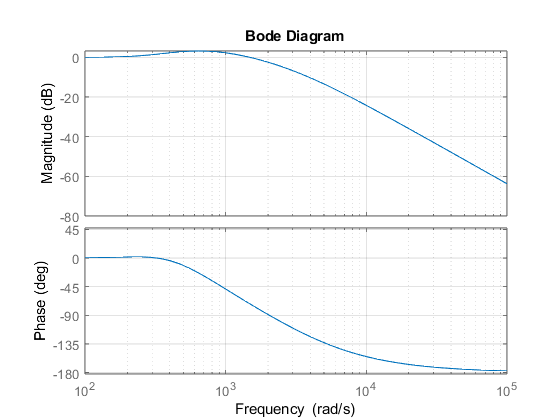

bode(Hv_num)
grid on

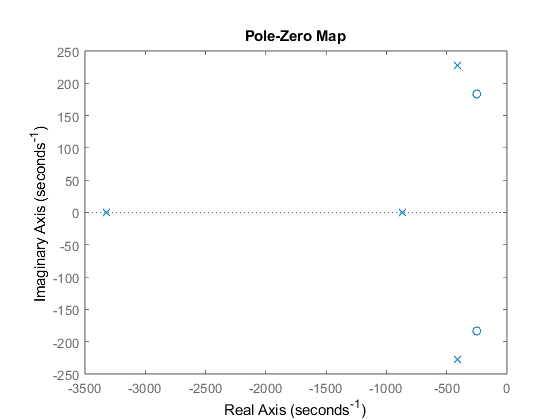


pzmap(Hv_num)

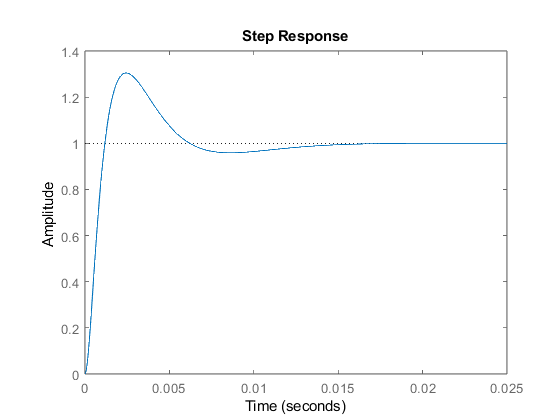

step(Hv_num)